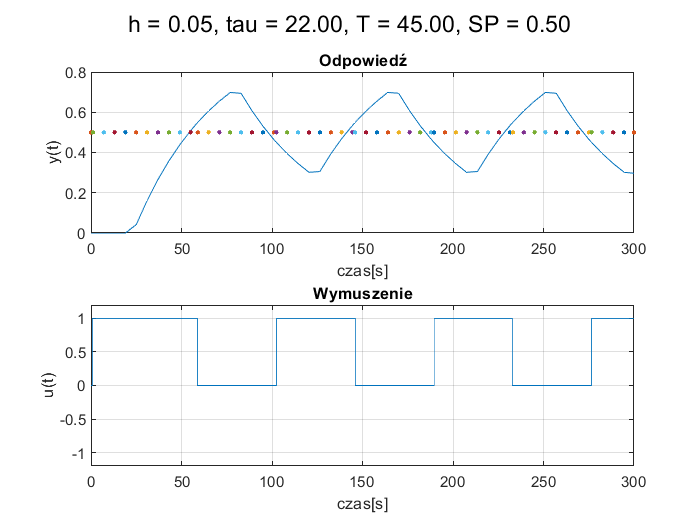

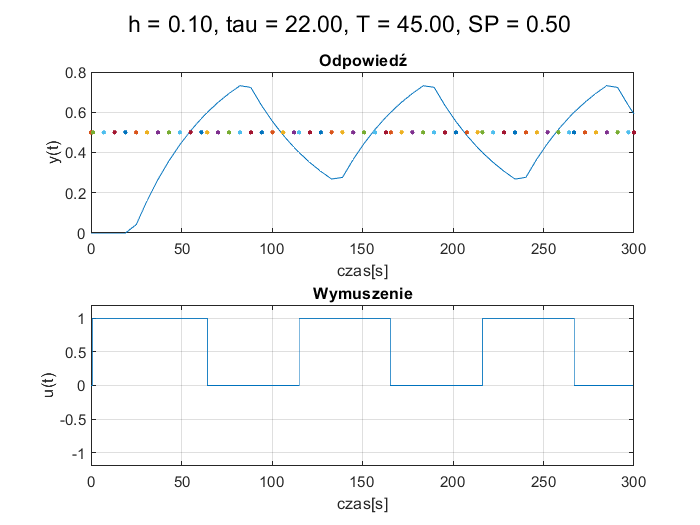

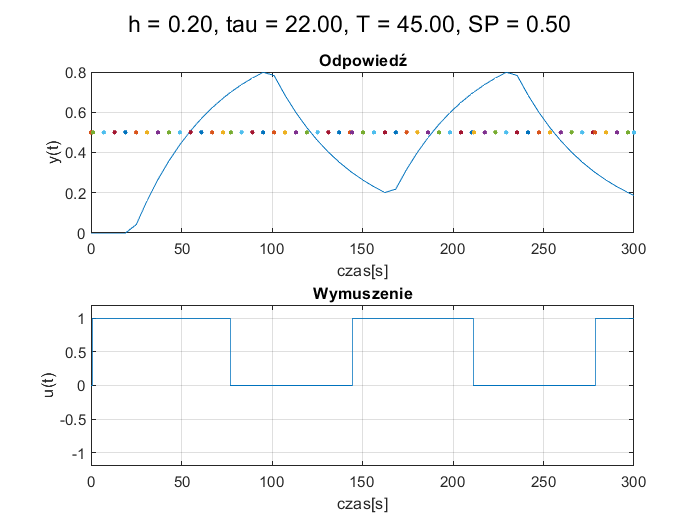

SP = 0.5;
T = 45;
tau = 22;
h = 0.05;
hi = [0.05, 0.1, 0.2];
taui = [10, 22, 35];
Ti = [25, 45, 60];
SPi = [0.2, 0.5, 0.9];

for i = 1:3
    h = hi(i);
    out = sim('sim1');
    figure
    subplot(2,1,1)
    plot(out.y.time,out.y.signals.values,out.y.time,SP,'.')
    grid
    title("Odpowiedź")
    xlabel('czas[s]')
    ylabel('y(t)')
    subplot(2,1,2)
    plot(out.u.time,out.u.signals.values)
    grid
    title("Wymuszenie")
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,300,-1.2,1.2])
    sgtitle(sprintf('h = %.2f, tau = %.2f, T = %.2f, SP = %.2f', h, tau, T, SP))
end

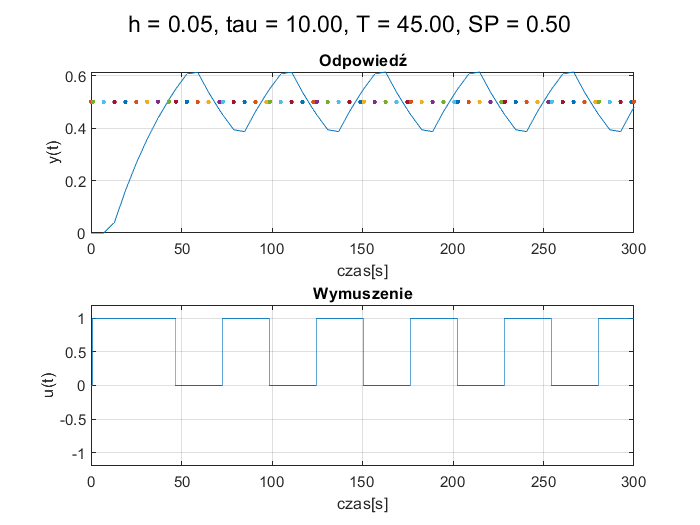

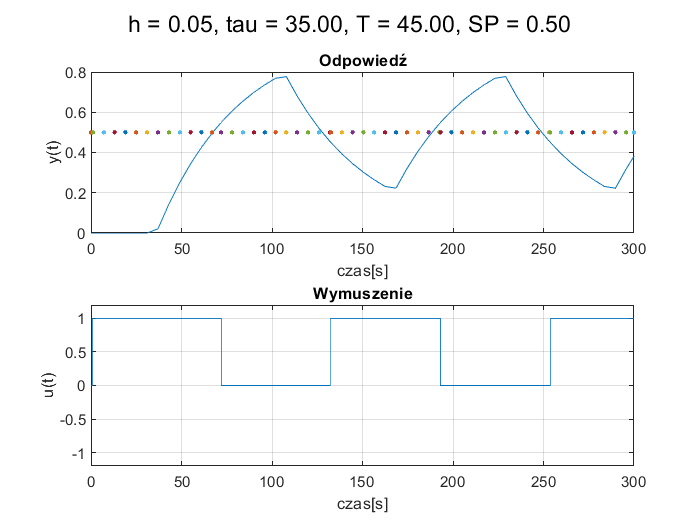


h = 0.05;

for i = 1:3
    tau = taui(i);
    out = sim('sim1');
    figure
    subplot(2,1,1)
    plot(out.y.time,out.y.signals.values,out.y.time,SP,'.')
    grid
    title("Odpowiedź")
    xlabel('czas[s]')
    ylabel('y(t)')
    subplot(2,1,2)
    plot(out.u.time,out.u.signals.values)
    grid
    title("Wymuszenie")
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,300,-1.2,1.2])
    sgtitle(sprintf('h = %.2f, tau = %.2f, T = %.2f, SP = %.2f', h, tau, T, SP))
end

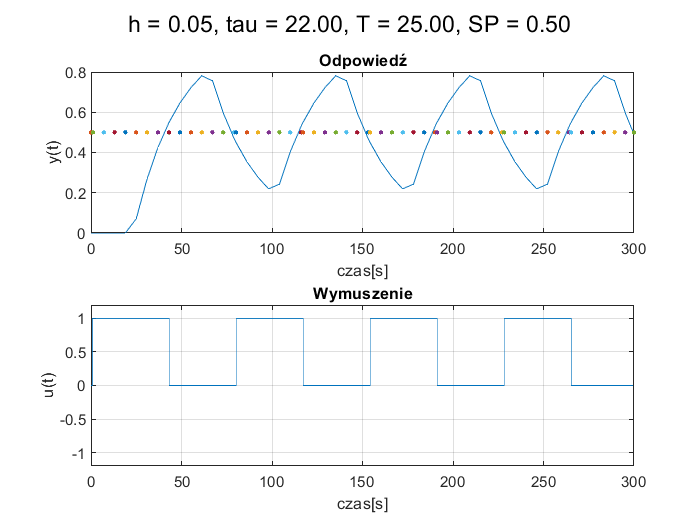

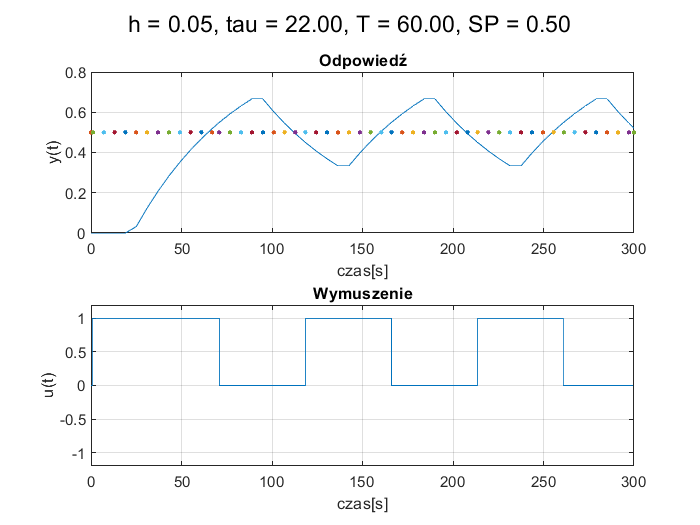


tau = 22;

for i = 1:3
    T = Ti(i);
    out = sim('sim1');
    figure
    subplot(2,1,1)
    plot(out.y.time,out.y.signals.values,out.y.time,SP,'.')
    grid
    title("Odpowiedź")
    xlabel('czas[s]')
    ylabel('y(t)')
    subplot(2,1,2)
    plot(out.u.time,out.u.signals.values)
    grid
    title("Wymuszenie")
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,300,-1.2,1.2])
    sgtitle(sprintf('h = %.2f, tau = %.2f, T = %.2f, SP = %.2f', h, tau, T, SP))
end

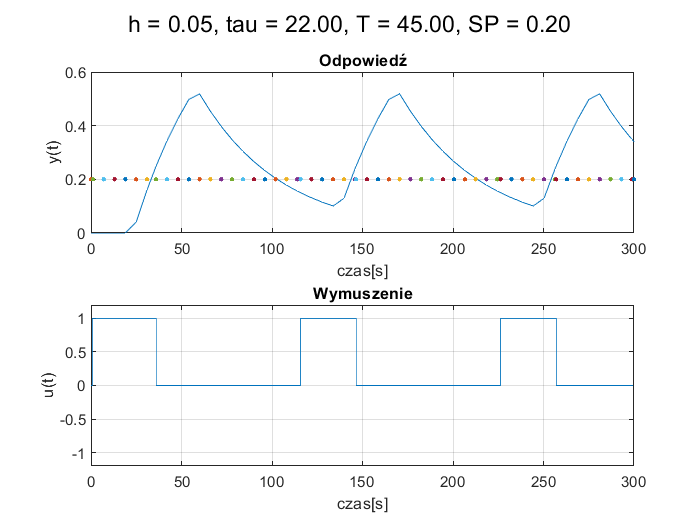

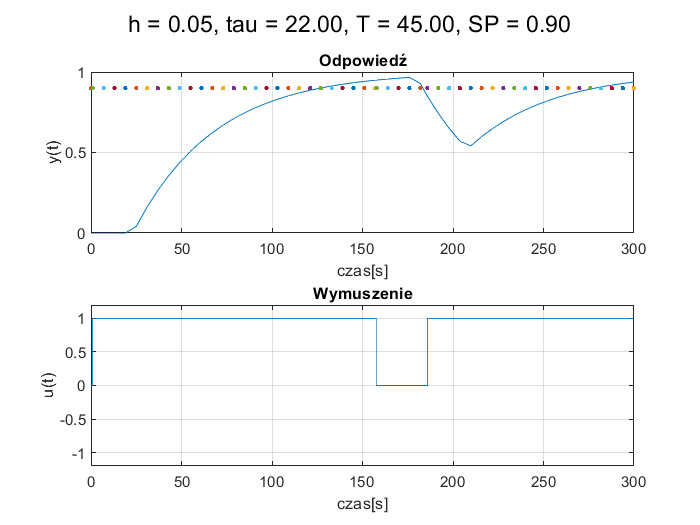


T = 45;

for i = 1:3
    SP = SPi(i);
    out = sim('sim1');
    figure
    subplot(2,1,1)
    plot(out.y.time,out.y.signals.values,out.y.time,SP,'.')
    grid
    title("Odpowiedź")
    xlabel('czas[s]')
    ylabel('y(t)')
    subplot(2,1,2)
    plot(out.u.time,out.u.signals.values)
    grid
    title("Wymuszenie")
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,300,-1.2,1.2])
    sgtitle(sprintf('h = %.2f, tau = %.2f, T = %.2f, SP = %.2f', h, tau, T, SP))
end

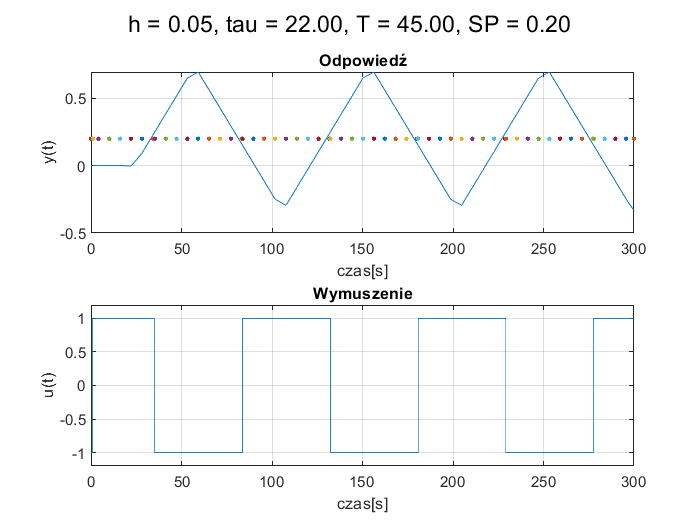

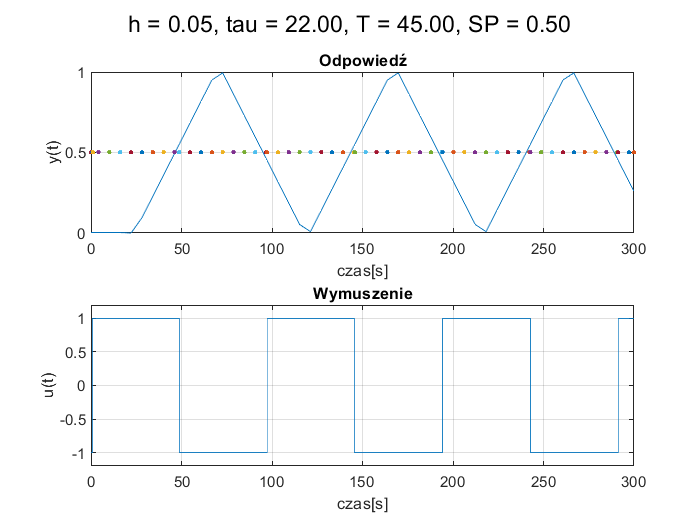

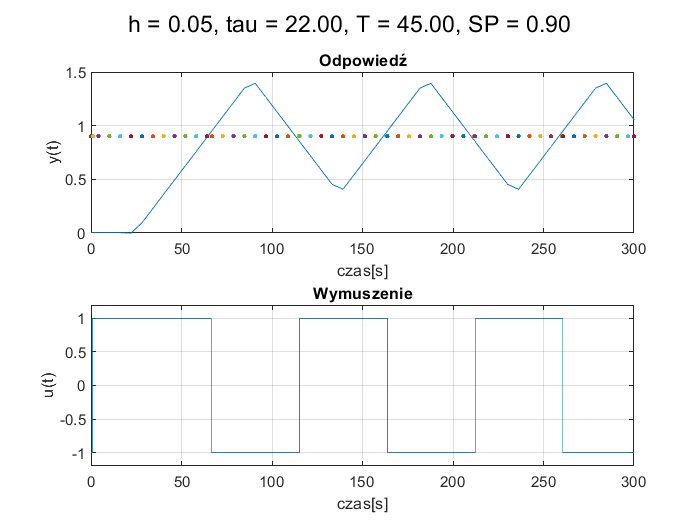


SP = 0.5;


T = 45;
tau = 22;
h = 0.05;
SPi = [0.2, 0.5, 0.9];

for i = 1:3
    SP = SPi(i);
    out = sim('sim2');
    figure
    subplot(2,1,1)
    plot(out.y.time,out.y.signals.values,out.y.time,SP,'.')
    grid
    title("Odpowiedź")
    xlabel('czas[s]')
    ylabel('y(t)')
    subplot(2,1,2)
    plot(out.u.time,out.u.signals.values)
    grid
    title("Wymuszenie")
    xlabel('czas[s]')
    ylabel('u(t)')
    axis([0,300,-1.2,1.2])
    sgtitle(sprintf('h = %.2f, tau = %.2f, T = %.2f, SP = %.2f', h, tau, T, SP))
end